## **Parametri**

m_punto=0.05;   % portata [kg/s]
rho_l=1000;     % densità liquido [kg/m^3]
n=3;            % numero scanalature
theta=pi/6;     % angolo inclinazione scanalature [rad]
d_w=0.018;       % diametro inserto [m]
rho_a=1.125;    % densità aria [kg/m^3]
sigma=0.073;    % tensione superficiale [N/m]
mi_l=0.001;     % viscosità liquido [Pa*s]


## **Parametri di simulazione**

dDP = 1000;        % Passo di integrazione [Pa]
DPsim = 7000000;   % Pressione di simulazione [Pa]

## I**ntegrazione numerica: metodo di Eulero**

% Dichiarazione di d0
d0 = zeros(1, 1+round(DPsim/dDP));

%integrazione numerica

for i=1:1+round(DPsim/dDP) %serie incremento unitario 
    DP(i)=(i-1)*dDP; %vettore DP con indice iesimo

    c_d(i)=0.9*((0.676-24*d0(i)))^0.13;
    d0(i)=((4*m_punto)/(c_d(i)*(2*10*rho_l*DP(i))^0.5))^0.5;
    da(i)=(d0(i)*(0.676-24*d0(i))^0.5);
    As(i)=4.3*3.14*0.25*(da(i))^2;
    a(i)=(As(i)/(n*cos(theta)))^0.5;
    alfa(i)=180/(pi)*2*atan(4*(d_w*0.5-a(i)*0.5)/(d0(i))*(sin(theta)*(pi*(d0(i))^2*0.25*As(i))/(pi*(da(i))^2*0.25+As(i))^2));
    SMD(i)=d0(i)*3.67*((2*rho_a*DP(i)*d0(i)/sigma)^0.5*(rho_l*d0(i)*(2 * DP(i)/rho_l)^0.5)/mi_l)^(-0.259);


end

## **Grafici **

**Grafico DP-alfa**

figure,
plot(DP, alfa,'LineWidth', 2)

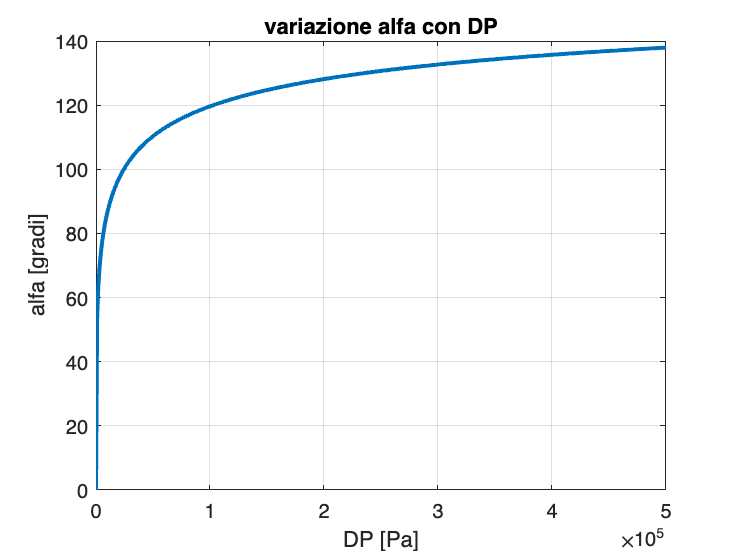

xlabel('DP [Pa]')
ylabel('alfa [gradi]')
title('variazione alfa con DP')
grid on
xlim([0,500000])


% Cerco il valore di alfa a DP=100000
DP_1 = 100000;

% Trova l'indice del valore DP più vicino
[~, indice] = min(abs(DP - DP_1));

% Valore di alfa corrispondente
alfa_1 = alfa(indice);

% Visualizza il valore di alfa corrispondente
fprintf('DP= %d alfa= %.2f\n', DP_1, alfa_1);

DP= 100000 alfa= 119.63


**Grafico DP-c_d**

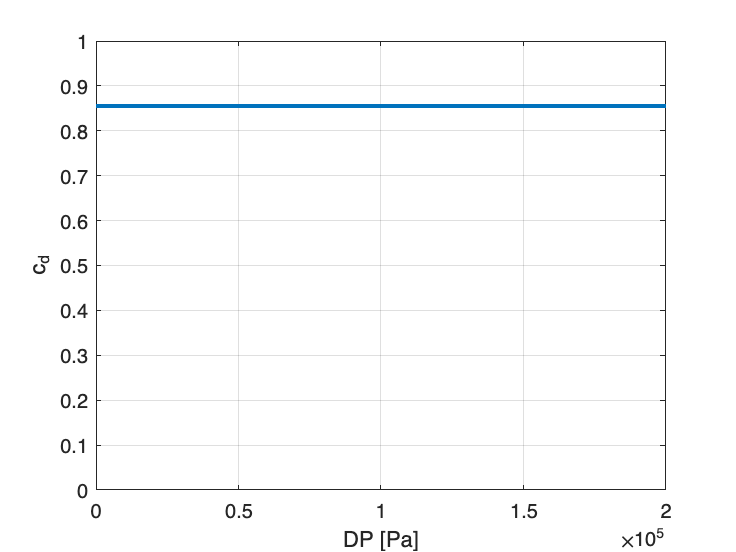

figure,
plot(DP,c_d,'LineWidth', 2)
xlim([0,200000])
ylim([0,1])
grid on
xlabel('DP [Pa]')
ylabel('c_d')


% Cerco il valore di c_d a DP=100000
DP_1 = 100000;

% Trova l'indice del valore DP più vicino
[~, indice] = min(abs(DP - DP_1));

% Valore di c_d corrispondente
c_d_1 = c_d(indice);

% Visualizza il valore di c_d corrispondente
fprintf('DP= %d c_d= %.3f\n', DP_1, c_d_1);

DP= 100000 c_d= 0.855


**Grafico DP-SMD**

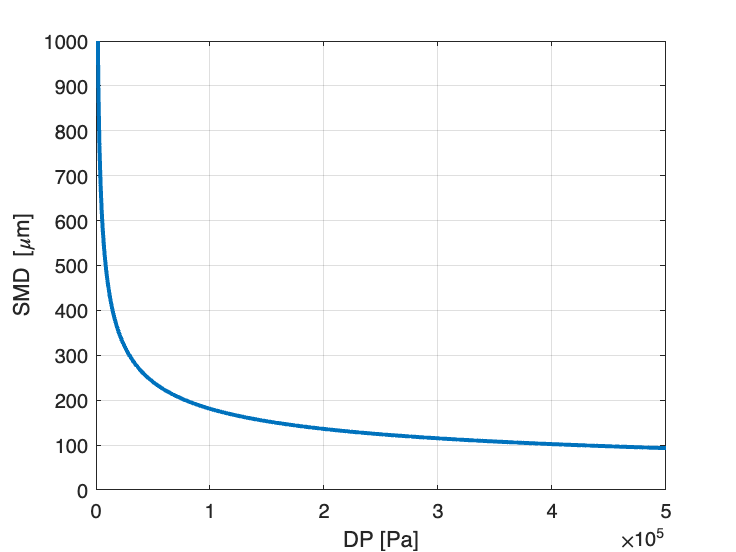


figure,
plot(DP,SMD*1e6,'LineWidth',2)
xlabel('DP [Pa]')
ylabel('SMD [\mum]')
xlim([0,500000])
ylim([0,1000])
grid on

## **Risultati**

% Cerco il valore di SMD a DP=100000
DP_1 = 100000;
[~, indice] = min(abs(DP - DP_1));
SMD_1 = SMD(indice);
fprintf('DP= %d SMD= %.6f\n', DP_1, SMD_1);

DP= 100000 SMD= 0.000181



% Cerco il valore di d0 a DP=100000
DP_1 = 100000;
[~, indice] = min(abs(DP - DP_1));
d0_1 = d0(indice);
fprintf('DP= %d d0= %.5f\n', DP_1, d0_1);

DP= 100000 d0= 0.00229



% Cerco il valore di da a DP=100000
DP_1 = 100000;
[~, indice] = min(abs(DP - DP_1));
da_1 = da(indice);
fprintf('DP= %d da= %.5f\n', DP_1, da_1);

DP= 100000 da= 0.00180



% Cerco il valore di a a DP=100000
DP_1 = 100000;
[~, indice] = min(abs(DP - DP_1));
a_1 = a(indice);
fprintf('DP= %d a= %.5f\n', DP_1, a_1);

DP= 100000 a= 0.00205
